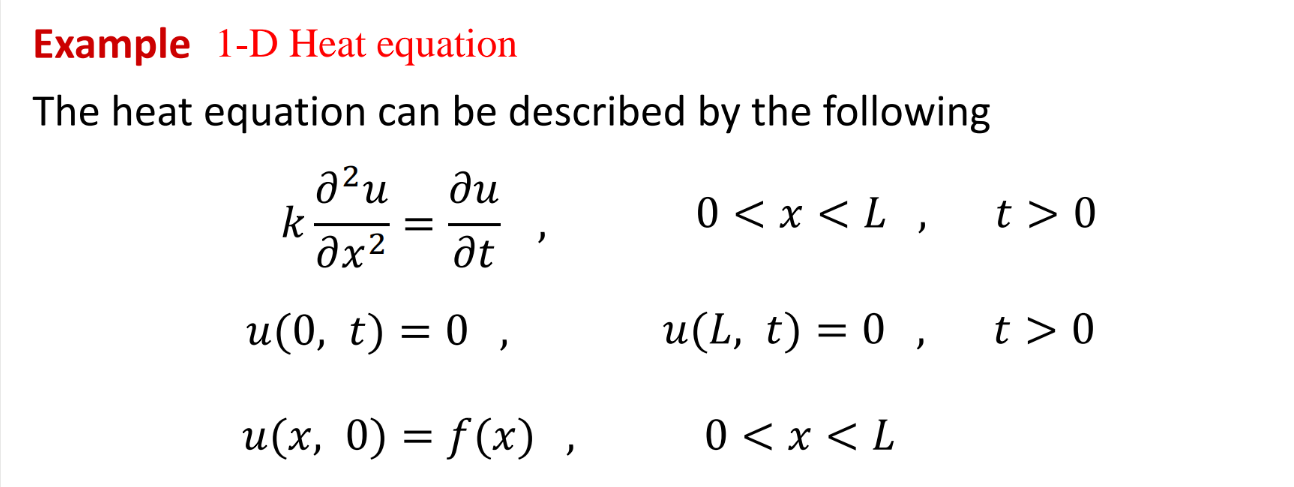

clear
clf
syms u(x,t) x k t L
assume([L k],"positive")

**PDE**

Eq = k*diff(u,x,2) == diff(u,t)

$$Eq(x, t) = k\,\frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)=\frac{\partial }{\partial t}u\left(x,t\right)$$

**Seperate Var.**

syms X(x) T(t)
SepVar = subs(Eq,u(x,t),X(x)*T(t))

$$SepVar(x, t) = k\,T\left(t\right)\,\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)=X\left(x\right)\,\frac{\partial }{\partial t}T\left(t\right)$$

SepVar = SepVar/(k*T(t)*X(x))%จัดรูปให้มันอยู่ข้างเดียวกัน

$$SepVar(x, t) = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=\frac{\frac{\partial }{\partial t}T\left(t\right)}{k\,T\left(t\right)}$$

**Boundary condition**

BC0 = u(0,t) == 0; BCL = u(L,t) == 0;

**Seperation for BC**

BCx0 = subs(BC0,u(0,t),X(0)*T(t)/T(t))

$$BCx0 = X\left(0\right)=0$$

BCxL = subs(BCL,u(L,t),X(L)*T(t)/T(t))

$$BCxL = X\left(L\right)=0$$

**Seperate ODEs introduce constant(Lambda)^2**

var = children(SepVar);
syms lambda;
assume(lambda,"positive");
eqX = var(1) == -lambda^2

$$eqX = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\lambda^{2}$$

eqT = var(2) == -lambda^2

$$eqT = \frac{\frac{\partial }{\partial t}T\left(t\right)}{k\,T\left(t\right)}=-\lambda^{2}$$

T(t,lambda) = dsolve(eqT)

$$T(t, lambda) = C_{1}\,{\mathrm{e}}^{-k\,\lambda^{2}\,t}$$

X(x,lambda) = dsolve(eqX,BCx0)

$$X(x, lambda) = -C_{1}\,\sin\left(\lambda \,x\right)$$

constantX = setdiff(symvar(X(x,lambda)),sym(['C',x,lambda]));
X(x,lambda) = subs(-X(x,lambda),constantX,sym('C2'))

$$X(x, lambda) = C_{2}\,\sin\left(\lambda \,x\right)$$

**Slove the right boundary condition wrt. to lambda:X(L) = 0**

sln = X(L,lambda);
[lambda,parameters,condition] = solve(sln == 0,lambda,"ReturnConditions",true)

$$lambda = \frac{\pi \,k}{L}$$

$$parameters = k$$

$$condition = k\in \mathbb{Z}\wedge C_{2}\neq 0\wedge 1\leq k$$

**Add an arbittrary multiplier (replace l with n)**

n = sym("n",["integer","positive"]);
lambda = subs(lambda,parameters,n)

$$lambda = \frac{\pi \,n}{L}$$

**Replace lambda = n*Pi/L and b_n = C2**

syms b_n ustruct(x,t,n)
expT(t,n) = subs(T(t,lambda),[lambda,sym('C1')],[lambda,sym('1')]);
sinX(x,n) = subs(X(x,lambda),[lambda,sym('C2')],[lambda,b_n]);

**Back to product solution**

ustruct(x,t,n) = collect(sinX(x,n)*expT(t,n),["sin","exp"])

$$ustruct(x, t, n) = b_{n}\,{\mathrm{e}}^{-\frac{k\,n^{2}\,t\,\pi^{2}}{L^{2}}}\,\sin\left(\frac{\pi \,n\,x}{L}\right)$$

**From symbolic to function handle**

SinXExpTfun = matlabFunction(ustruct)

SinXExpTfun = function_handle with value:
    @(x,t,n,L,b_n,k)b_n.*exp(-1.0./L.^2.*k.*n.^2.*t.*pi.^2).*sin((n.*x.*pi)./L)


syms x m n L
assume([m,n],["integer","positive"]); assume(L,"positive"); assumeAlso(not(L == pi));
lambda(n) = n*pi/L;
e(n) = sin(lambda(n)*x)

$$e(n) = \sin\left(\frac{\pi \,n\,x}{L}\right)$$

check_orthogonality = int(e(n)*e(m),0,L)

$$check\_orthogonality = \left\{ \begin{array}{cl} \frac{L}{2} & \text{ if }m=n\\ 0 & \text{ if }m\neq n \end{array}\right.$$

**Emabed ****Fourier coefficients**** into Heat structure to get solution**

syms x t b(n) phi(x)
assume(n,"integer")
L = 4

L = 4

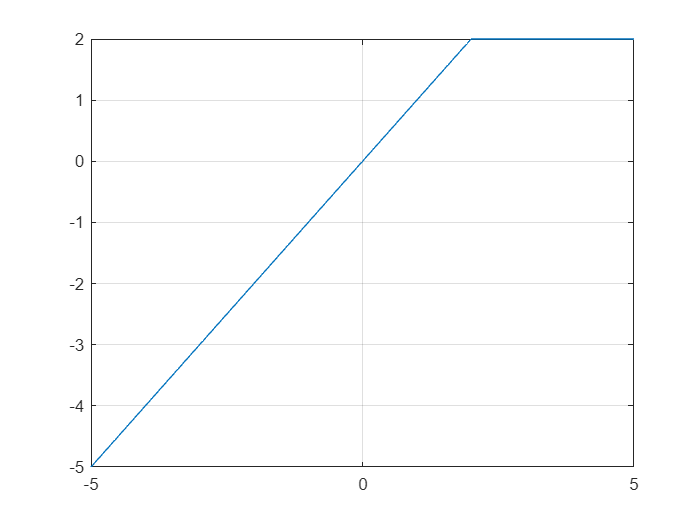

phi(x) = piecewise(x<L/2,x,x>L/2,L/2);
fplot(phi),grid on

k = 0.1;
N = 8

N = 8

**Compute Fourier coefficients using phi(x) and L**

b(n) = simplify(2/L*int(phi(x)*sin(n*x*pi/L),0,L))

$$b(n) = \frac{8\,n\,\pi \,{\sin\left(\frac{\pi \,n}{2}\right)}^{2}+8\,\sin\left(\frac{\pi \,n}{2}\right)-4\,\pi \,n}{n^{2}\,\pi^{2}}$$

**Build Heat structure**

heatstruct = ustruct

$$heatstruct(x, t, n) = b_{n}\,{\mathrm{e}}^{-\frac{k\,n^{2}\,t\,\pi^{2}}{L^{2}}}\,\sin\left(\frac{\pi \,n\,x}{L}\right)$$

**Embedding b(n) and k in the Heat structure**

heatstructEmb(x,t,n) = subs(ustruct,sym(["b_n" "L" "k"]),[b L k])

$$heatstructEmb(x, t, n) = \frac{\sin\left(\frac{\pi \,n\,x}{4}\right)\,{\mathrm{e}}^{-\frac{n^{2}\,t\,\pi^{2}}{160}}\,\left(8\,n\,\pi \,{\sin\left(\frac{\pi \,n}{2}\right)}^{2}+8\,\sin\left(\frac{\pi \,n}{2}\right)-4\,\pi \,n\right)}{n^{2}\,\pi^{2}}$$

**Heat solution**

Solution = symsum(heatstructEmb,n,1,inf)

$$Solution(x, t) = \frac{\sum_{n=1}^{\infty }\frac{\sin\left(\frac{\pi \,n\,x}{4}\right)\,{\mathrm{e}}^{-\frac{n^{2}\,t\,\pi^{2}}{160}}\,\left(8\,n\,\pi \,{\sin\left(\frac{\pi \,n}{2}\right)}^{2}+8\,\sin\left(\frac{\pi \,n}{2}\right)-4\,\pi \,n\right)}{n^{2}}}{\pi^{2}}$$

**Build the solution by summing up N terms of the series**

heatSolN = simplify(symsum(heatstructEmb,n,1,N))

$$heatSolN(x, t) = \begin{array}{l} \frac{{\mathrm{e}}^{-\frac{5\,t\,\pi^{2}}{32}}\,\sin\left(\frac{5\,\pi \,x}{4}\right)\,\left(20\,\pi +8\right)}{25\,\pi^{2}}-\frac{{\mathrm{e}}^{-\frac{t\,\pi^{2}}{10}}\,\sin\left(\pi \,x\right)}{\pi }-\frac{2\,{\mathrm{e}}^{-\frac{t\,\pi^{2}}{40}}\,\sin\left(\frac{\pi \,x}{2}\right)}{\pi }-\frac{2\,{\mathrm{e}}^{-\frac{\sigma_{1}}{40}}\,\sin\left(\frac{3\,\pi \,x}{2}\right)}{3\,\pi }-\frac{{\mathrm{e}}^{-\frac{2\,t\,\pi^{2}}{5}}\,\sin\left(2\,\pi \,x\right)}{2\,\pi }+\frac{{\mathrm{e}}^{-\frac{t\,\pi^{2}}{160}}\,\sin\left(\frac{\pi \,x}{4}\right)\,\left(4\,\pi +8\right)}{\pi^{2}}+\frac{{\mathrm{e}}^{-\frac{\sigma_{1}}{160}}\,\sin\left(\frac{3\,\pi \,x}{4}\right)\,\left(12\,\pi -8\right)}{9\,\pi^{2}}+\frac{{\mathrm{e}}^{-\frac{49\,t\,\pi^{2}}{160}}\,\sin\left(\frac{7\,\pi \,x}{4}\right)\,\left(28\,\pi -8\right)}{49\,\pi^{2}}\\ \mathrm{where}\\ \sigma_{1}=9\,t\,\pi^{2} \end{array}$$

**Visualize**

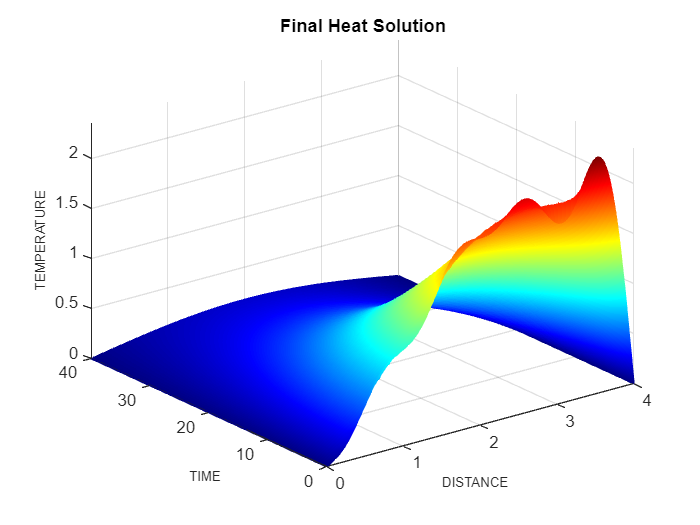

clf
figure
colormap jet
tau = L^2/k;
fsurf(heatSolN,[0 L 0 tau/4],"EdgeColor","interp")
title("Final Heat Solution")
xlabel('DISTANCE','FontSize',8);
ylabel('TIME',"FontSize",8)
zlabel('TEMPERATURE','FontSize',8)

**Lambda = 0**

T(t) = dsolve(subs(eqT,lambda,0));
X(x) = dsolve(subs(eqX,lambda,0));
U_0(x,t) = X(x)*T(t)

$$U\_0(x, t) = C_{1}\,{\mathrm{e}}^{-k\,\lambda^{2}\,t}\,\left(C_{1}\,\cos\left(\lambda \,x\right)-C_{2}\,\sin\left(\lambda \,x\right)\right)$$

X = subs(U_0,x,0) == 0

$$X(x, t) = {C_{1}}^{2}\,{\mathrm{e}}^{-k\,\lambda^{2}\,t}=0$$

**Lambda = -alpha^2**

syms alpha
T(t) = dsolve(subs(eqT,lambda,-alpha^2));
X(x) = dsolve(subs(eqX,lambda,-alpha^2));
U_N(x,t) = rewrite(X(x)*T(t),"sincos")

$$U\_N(x, t) = C_{1}\,\left(C_{1}\,\cos\left(\lambda \,x\right)-C_{2}\,\sin\left(\lambda \,x\right)\right)\,\left(\cos\left(k\,\lambda^{2}\,t\,\mathrm{i}\right)+\sin\left(k\,\lambda^{2}\,t\,\mathrm{i}\right)\,\mathrm{i}\right)$$

X = subs(U_N,x,0) == 0

$$X(x, t) = {C_{1}}^{2}\,\left(\cos\left(k\,\lambda^{2}\,t\,\mathrm{i}\right)+\sin\left(k\,\lambda^{2}\,t\,\mathrm{i}\right)\,\mathrm{i}\right)=0$$

**Lambda = alpha^2**

T(t) = dsolve(subs(eqT,lambda,alpha^2));
X(x) = dsolve(subs(eqX,lambda,alpha^2))

$$X(x) = C_{1}\,\cos\left(\lambda \,x\right)-C_{2}\,\sin\left(\lambda \,x\right)$$

U_P(x,t) = X(x)*T(t)

$$U\_P(x, t) = C_{1}\,{\mathrm{e}}^{-k\,\lambda^{2}\,t}\,\left(C_{1}\,\cos\left(\lambda \,x\right)-C_{2}\,\sin\left(\lambda \,x\right)\right)$$

X = subs(U_P,x,0) == 0

$$X(x, t) = {C_{1}}^{2}\,{\mathrm{e}}^{-k\,\lambda^{2}\,t}=0$$